# Boat Project: HMS Swimmingly

### Swimmingly: If you're swimming, is it actually going well?

#### By Ari Porad and Aaron Blust, for Quantitative Engineering Analysis 2, March 14th, 2021

## Boat Design

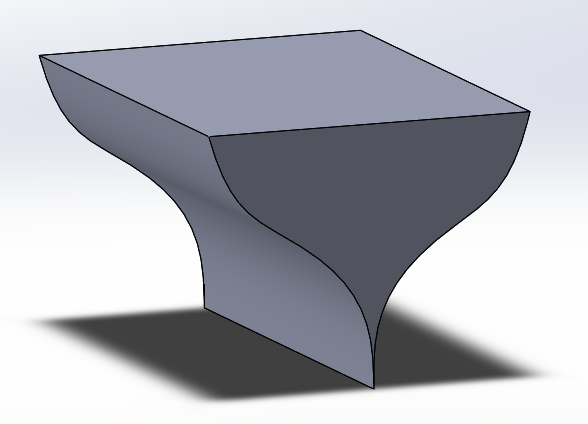

Our boat is designed using a polynomial function to model the shape of the hull. This 2D function is then extruded along the Y-axis to produce our overall boat. The boat is 3D-printed using two infill zones, one (the first, for the lowermost 37.2mm of the boat) at 100% infill to lower the boat's center of mass, then the other at 10% infill to reduce filament consumption and print time. The formula we used to model our boat's hull was:


$$y=\sqrt[3]{\frac{x}{a}}+{\left(\frac{x}{b}\right)}^8 \;\forall \;0\ldotp 006\mathrm{m}\le y\le 0\ldotp 065\mathrm{m}$$


We set $a=400$ and $b=0\ldotp 067$ after some testing to optimize for float stability, AVS, and aesthetic appearance.

setup % Prepare some internal objects and do some setup calculations

boat = struct with fields:
                W: 0.1000
                H: 0.0650
                L: 0.1200
                a: 400
                b: 0.0670
        infill_l1: 1
        infill_l2: 0.1000
    infill_cutoff: 0.0372
        predicate: @(boat,P)transpose(P(2,:)>=((abs(P(1,:))/boat.a).^(1/3)+((abs(P(1,:)/boat.b).^8)))&P(2,:)<=boat.H&P(2,:)>=0.01)


avs = 129.9298

## Stable Equilibrium

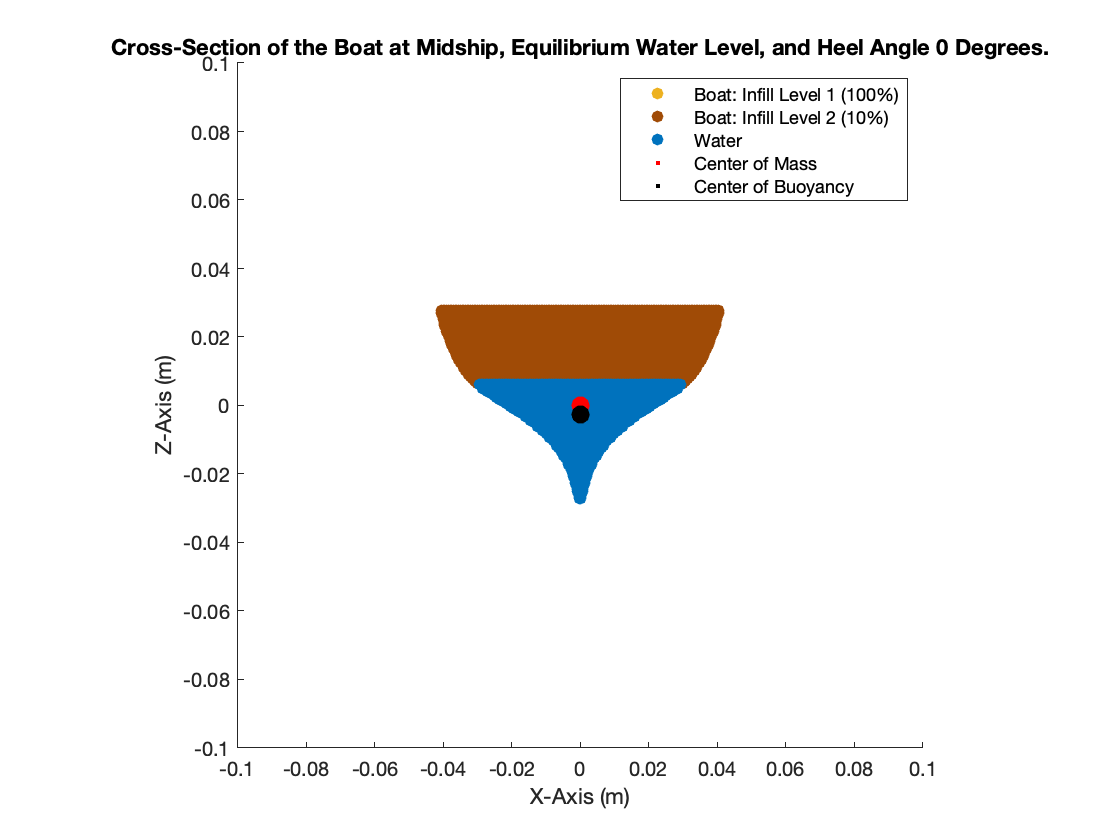

rboat = analyze_boat(boat, 0);
draw_boat(rboat, ...

    "Cross-Section of the Boat at Midship, Equilibrium Water Level, and Heel Angle 0 Degrees.")

### Displacement Ratio

displacement_ratio = calculate_displacement_ratio(rboat)

displacement_ratio = 0.3102

It will float because the displacement ratio is less than 1 meaning the density of the boat on average is less than water, meaning the mass of a volume of water equal to the volume of the boat would weigh more than the boat itself. We were able to acheive this displacement ratio through the use of two infill zones. The lowermost infill zone is printed at 100% infill to create a large mass lower on the boat, while the upper infill zone is printed at 10% infill to achieve a lower displacement ratio and to reduce printing time and filiment consumption. We used a parameter sweep to determine the optimal cutoff between the infill zones, focusing on achiving an angle of vanishing stability (AVS) of as close to 130 degrees as possible to best align with the project requirements. This resulted in an infill zone cutoff at 37.2mm from the bottom of the boat.

## Angle of Vanishing Stability

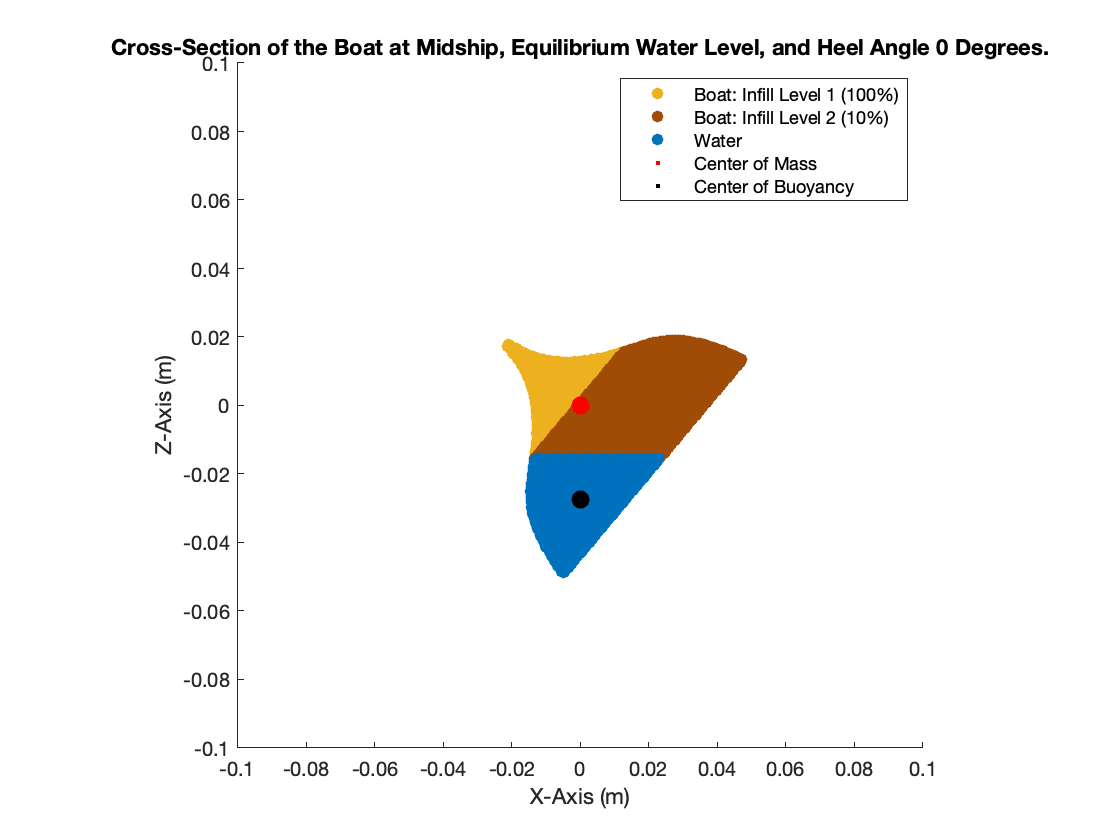

rboat = analyze_boat(boat, avs);
draw_boat(rboat, ...

    "Cross-Section of the Boat at Midship, Equilibrium Water Level, and Heel Angle 0 Degrees.")

Our boat's angle of vanishing stability is 130 degrees, well within the project's requirements of 120-140 degrees. This is easily identifiable as an equilibrium point because the boat's center of mass and center of bouyancy are vertically aligned.

## Moment Arm

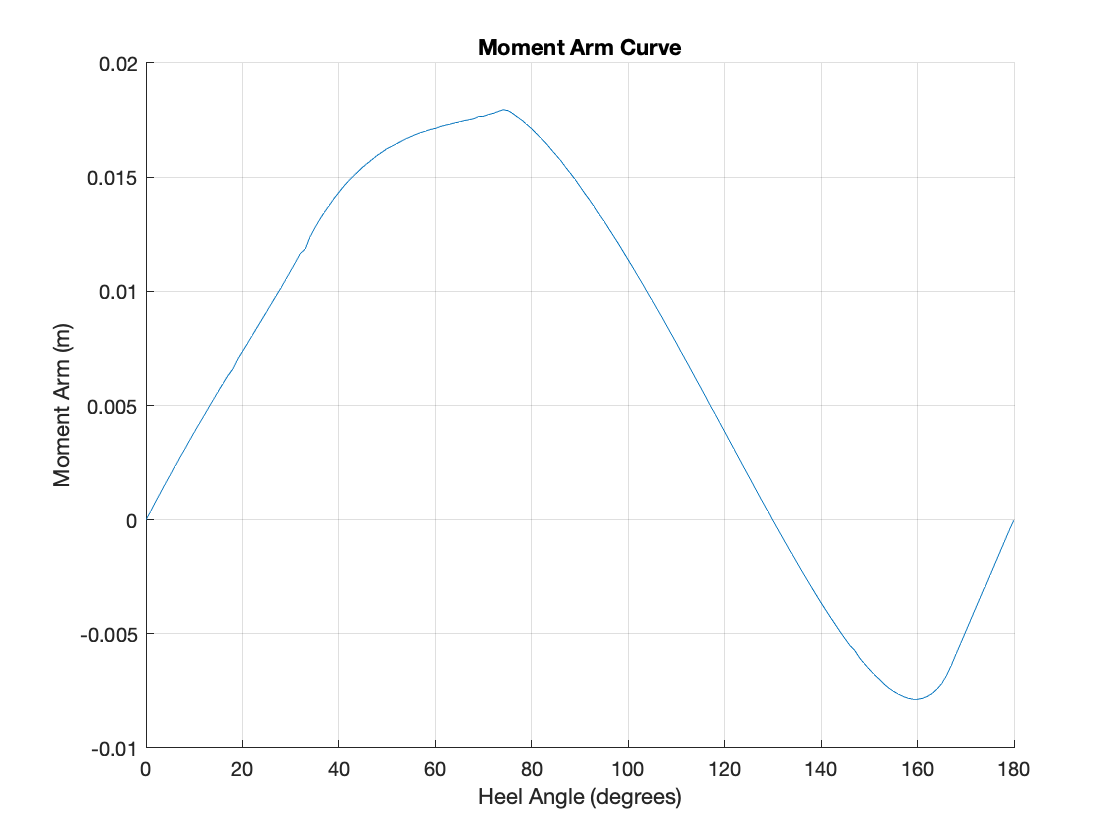

sweep_moment_arm(boat, 0, 1, 180, true, true)

This moment arm graph indicates that our boat is at stable equilibrium (moment arm is crossing zero with a positive slope) at a heel angle of 0 degrees, meaninng that it will float upright at that position. The graph also shows the boat's other equilibrium (where the moment arm curve crosses zero), at a heel angle of 130 degrees. This equilibrium is an unstable equilibrium, because the slope of the moment arm is negative, meaning that any disturbance will result in the boat being accelerated away from the equilibrium. As an unstable equilibrium, this point is also known as the angle of vanishing stability, or AVS. The AVS is the point after which the boat will flip over, instead of returning to its original position. A key design goal of this project was for the AVS to be between 120 and 140 degrees, which can be seen to be true from the graph. We modified the shape of our boat's hull to achive this goal, along with the goal of the boat floating flat at equilibrium, by modulating the shape to have a tall, skinny, heavy section (known as a keel) that protrudes beyond the bottom of the boat. This design feature helps with both AVS and floating stability.